# Problem set 1

## Problem 9

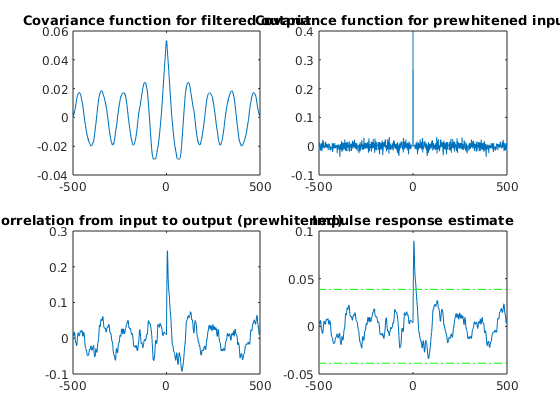

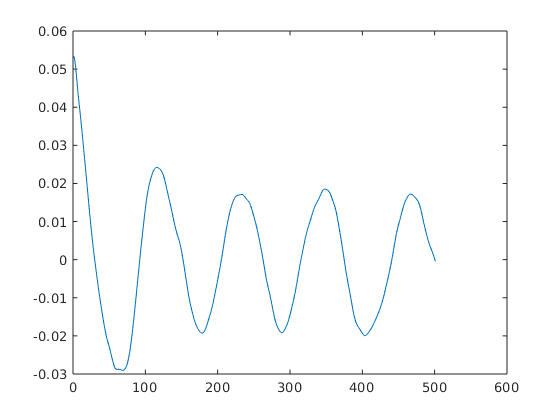

load('batch.mat')
Ts = 1;
data = iddata(y,u,Ts);
[ir, R, cl] = cra(data,500,[],2);

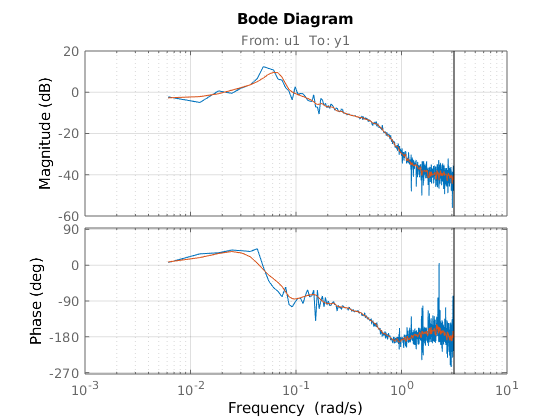

g_no_smoof = etfe(data,[],512);
g_smoof = etfe(data,250,512);
bode_opts = bodeoptions('cstprefs');
bode_opts.grid = 'on';
bode(g_no_smoof,g_smoof,bode_opts);

## Problem 10

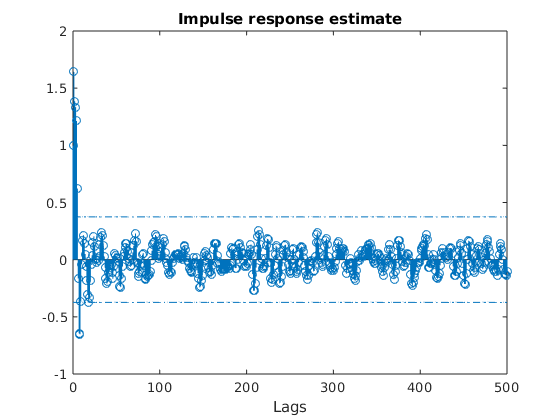

G0 = tf([1 -.05 0.2 0.8 0.1], [1 -1.7 1.6 -0.8 0.25],1);
H0 = tf([1],[1 -1.7 1.6 -0.8 0.25],1);
N = 1024;
u = sign(randn(N,1));
lambda = sqrt(0.1);
e = lambda*randn(N,1);
y = lsim(G0,u)+lsim(H0,e);
data = iddata(y,u,1);
[ir, R, cl] = cra(data,500);

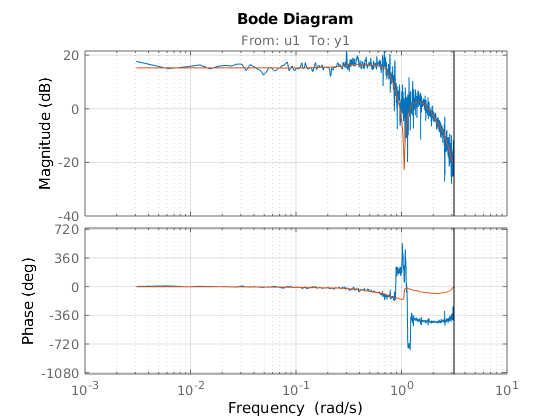

g_no_smoof = etfe(data,[],1024);
g_smoof = etfe(data,40,1024);
bode(g_no_smoof,g_smoof,bode_opts);

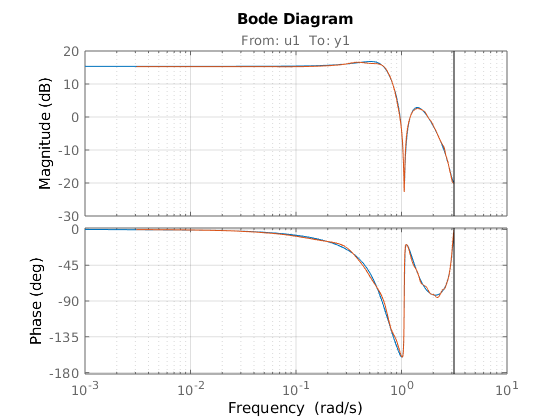

bode(G0,g_smoof,bode_opts);